# Question 1

Contact resistence exists where there are discontinuities in our materials. This could be where there is an interface between two different materials or where this some gap that interferes with the heat conductivity of the materials. 

# Question 2

We can determine that the system has reached a steady state when our termperature measurements between two differnt time steps is less than or equal to 0.1 or 0.2 degrees celcius 

# Question 3

In plotting this function I will be assuming a temerature of 100 celcius at the heater. A constant conductivity of copper of 


$$k= 
413
\frac{\text{W}}{\text{m K}}$$


This was sourced from the engineering toolbox 

[https://www.engineeringtoolbox.com/thermal-conductivity-metals-d_858.html?temperature_unit2=degC#](https://www.engineeringtoolbox.com/thermal-conductivity-metals-d_858.html?temperature_unit2=degC#)

k = 413; % [W / (m K)]

## Radial Distribution 

I will also be using the same parameters as those listed in the given excel sheet. 

T_H = 100 + 273.15; % [K]
r_H = 4e-3; % [m]
L = 3e-3; % [m]

I will also plot for all powers listed in the sheet 

Q = [5, 10, 15, 30, 45, 80]; % [W]

And I will be plottiting for positions from the heater radius to 55 milimeters 

I am plotting equation 9 from the lab handout 


$$T_i = 
T( r_H) - 
\frac{
\dot{Q}
}{
2 \pi L
}
\ln 
\left( 
\frac{r_i}{r_H}
\right) $$


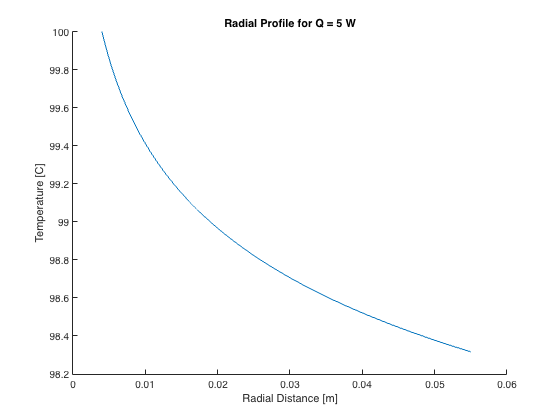

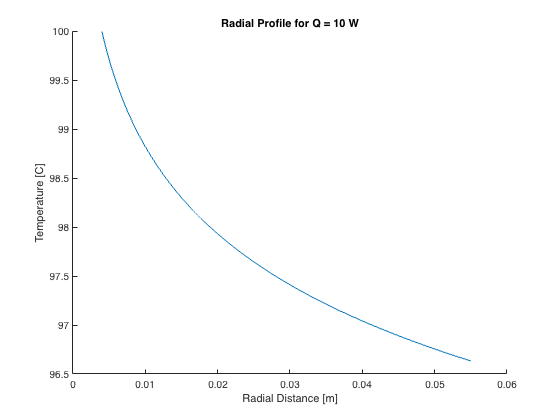

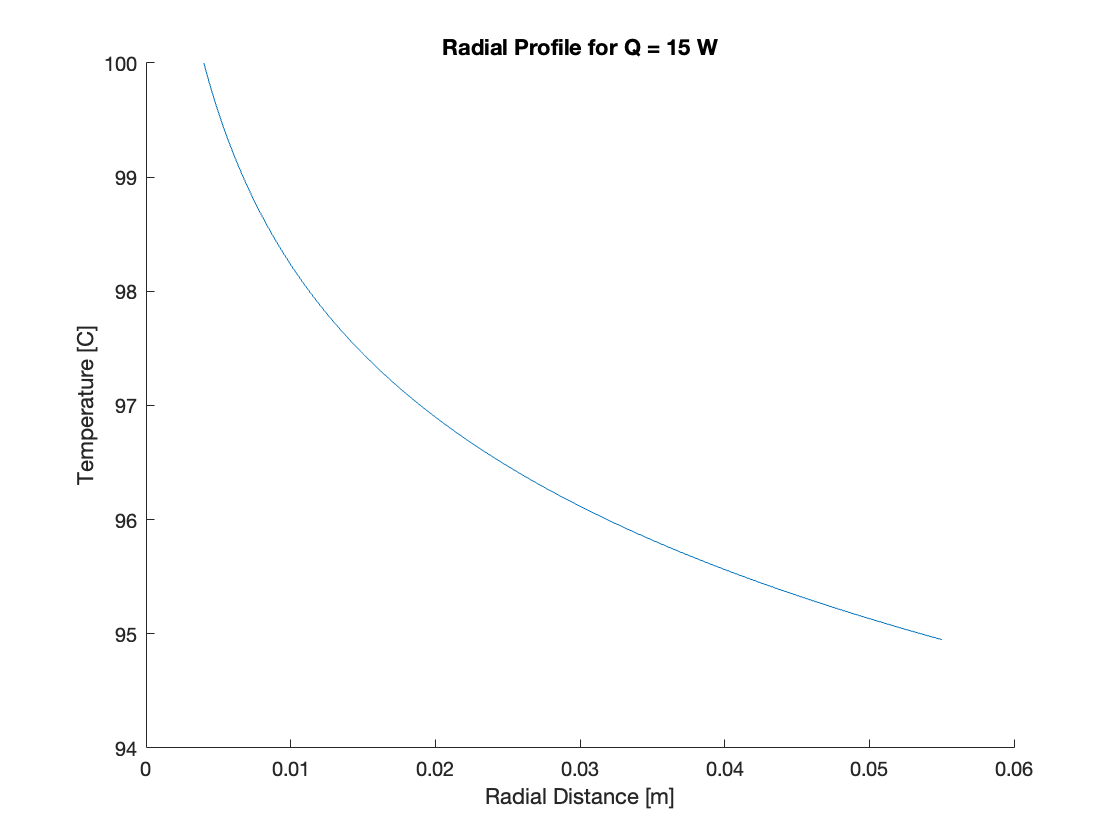

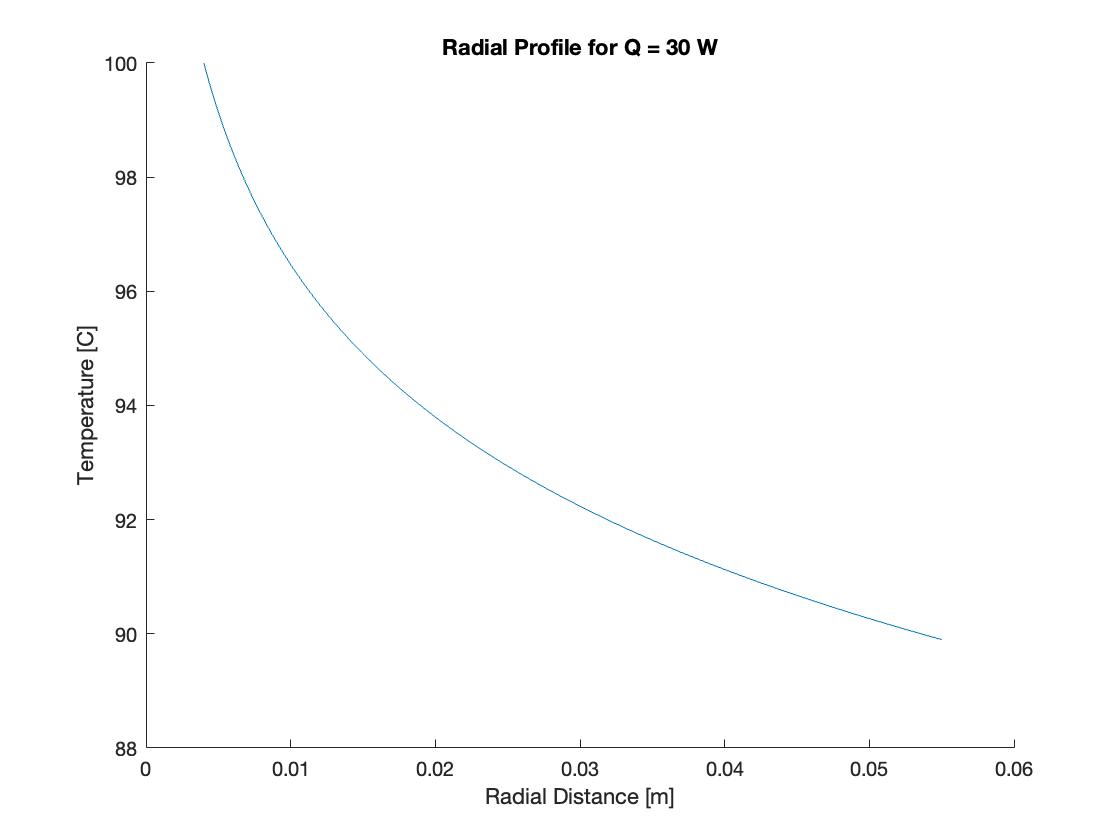

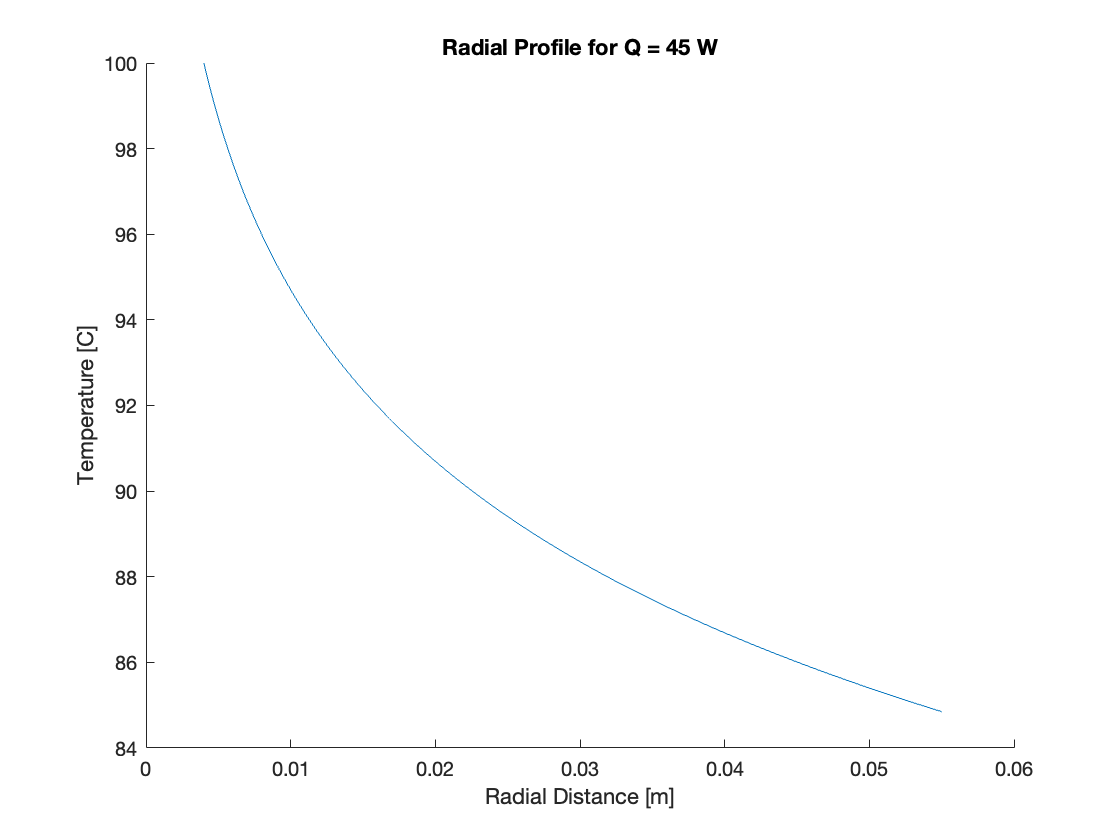

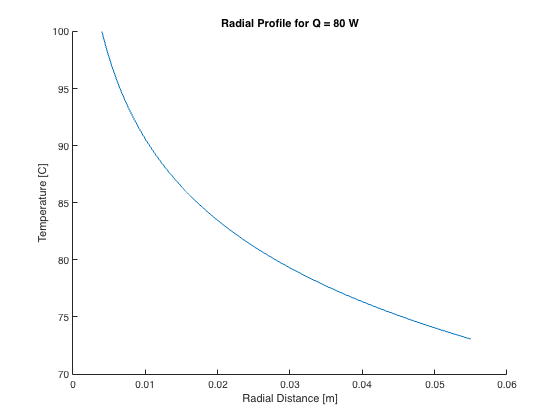

r = r_H:1e-5:55e-3; % [m]
r = r';
T = T_H - ( Q ./ ( 2 .* pi .* k .* L ) ) ...
          .* log( r ./ r_H ) - 273.15;

for i = 1:numel(Q)
    figure()
    hold on 
        plot( r, T( :, i ) )
        title( sprintf( "Radial Profile for Q = %d W",  Q( i ) ) ) 
        ylabel( "Temperature [C]" )
        xlabel( "Radial Distance [m]" )
    hold off
end 

This function is a logarithmic curve. 

##  Axial Distribution 

In plotting this distribution I will be assuming that there is just a continuous piece of copper. Starting at a distance of z = 10 mm to z = 90 mm. I will be using the equation 


$$T(z) = 
T_H - 
\frac{
\dot{Q}
}{
k A_0
}
\left( 
z - z_H
\right) $$


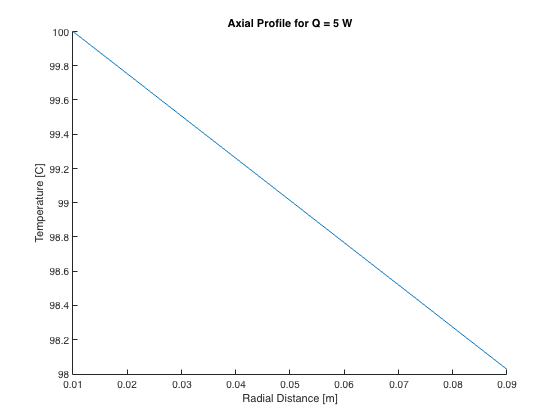

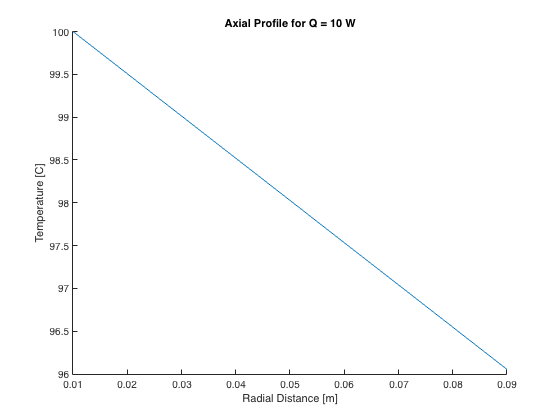

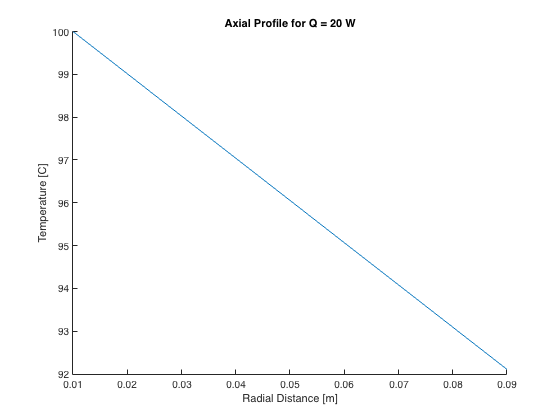

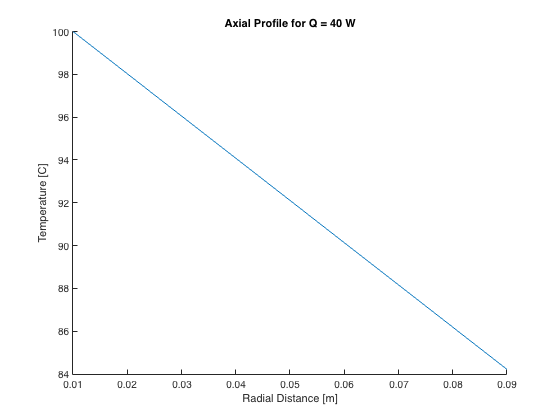

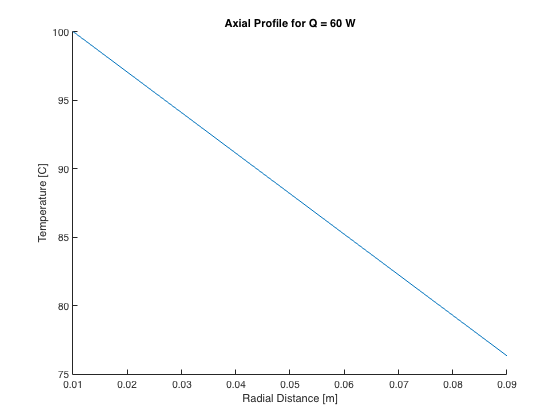

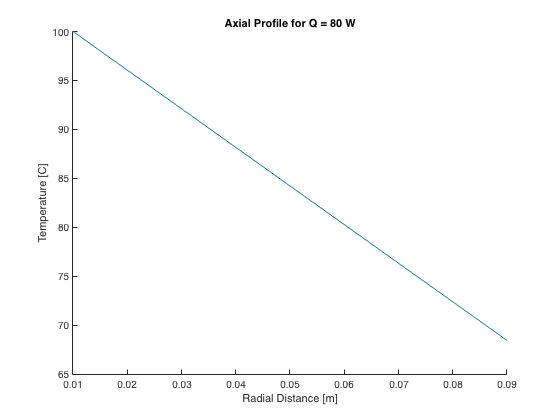

z_H = 10e-3; % [m]
z = z_H:1e-5:90e-3; % [m]
z = z';
A_0 = 490.9e-6; % [m^2]
Q = [5, 10, 20, 40, 60, 80]; % [W]


T = T_H - ( Q ./ ( k .* A_0 ) ) .* ( z - z_H ) - 273.15;
for i = 1:numel(Q)
    figure()
    hold on 
        plot( z, T( :, i ) )
        title( sprintf( "Axial Profile for Q = %d W",  Q( i ) ) ) 
        ylabel( "Temperature [C]" )
        xlabel( "Radial Distance [m]" )
    hold off
end 

This function is a linear curve. If there are gaps included then this is a piece-wise continuous linear curve. 